I = imread('bellen.tif')

I = 256×256 uint8 matrix
   208   209   209   208   205   206   203   204   204   203   203   204   202   201   201   203   199   200   199   198   198   198   198   196   197   198   197   196   191   194   195   194   191   191   194   191   191   191   189   191   189   189   187   187   185   185   185   186   186   182
   210   211   209   206   206   208   204   204   204   204   203   202   204   204   203   203   200   202   200   198   198   199   198   201   199   197   196   197   195   192   192   193   193   194   193   192   190   190   192   189   190   188   187   185   187   186   185   187   185   185
   210   209   207   206   206   207   206   206   204   207   205   204   204   201   202   202   201   201   201   199   200   198   200   196   199   197   195   197   194   196   195   193   195   194   194   194   190   192   189   187   190   189   188   189   189   187   186   186   183   185
   209   210   209   211   208   207   209   208   205   206   205   204

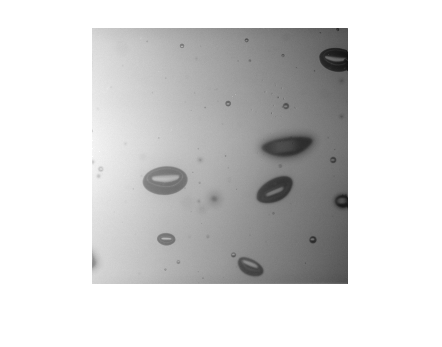

imshow(I)


tilesize = 100;
sampling = 50;
counter = 0;
size(I, 1)/sampling

ans = 5.1200

size(I, 1)/sampling + 1

ans = 6.1200

floor(size(I, 1)/sampling + 1)

ans = 6


tiles = zeros(floor(size(I,1)/sampling+1)*floor(size(I, 2) /sampling +1), 4)

tiles =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


i = 1

ans =      1     1   100   100


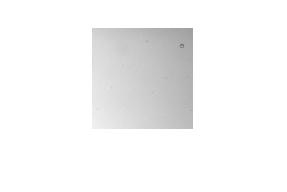

i = 2

ans =      1    51   100   100


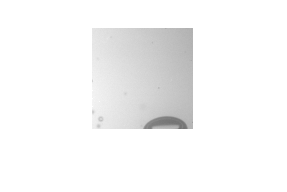

i = 3

ans =      1   101   100   100


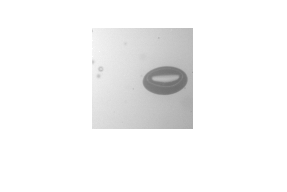

i = 4

ans =      1   151   100   100


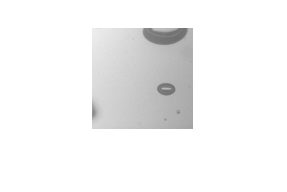

i = 5

ans =      1   201   100   100


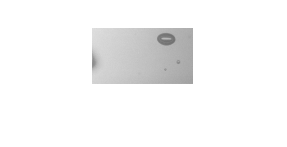

i = 6

ans =      1   251   100   100


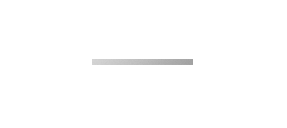

i = 7

ans =     51     1   100   100


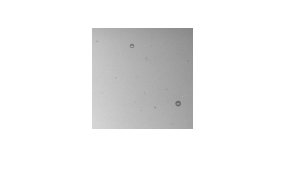

i = 8

ans =     51    51   100   100


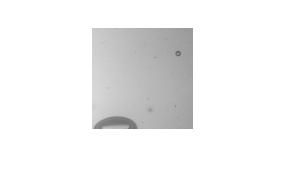

i = 9

ans =     51   101   100   100


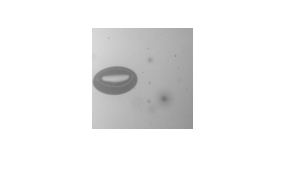

i = 10

ans =     51   151   100   100


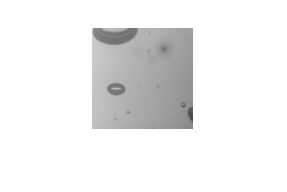

i = 11

ans =     51   201   100   100


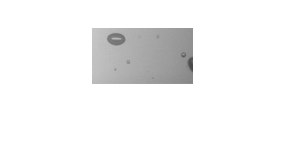

i = 12

ans =     51   251   100   100


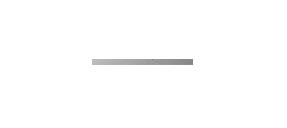

i = 13

ans =    101     1   100   100


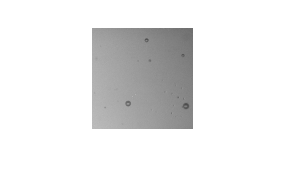

i = 14

ans =    101    51   100   100


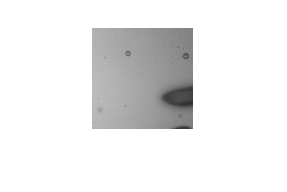

i = 15

ans =    101   101   100   100


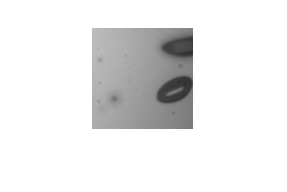

i = 16

ans =    101   151   100   100


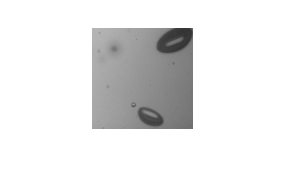

i = 17

ans =    101   201   100   100


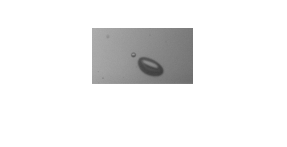

i = 18

ans =    101   251   100   100


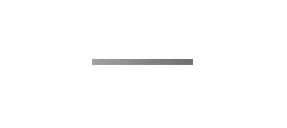

i = 19

ans =    151     1   100   100


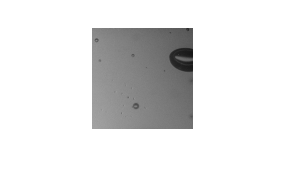

i = 20

ans =    151    51   100   100


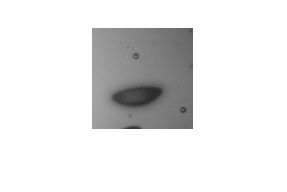

i = 21

ans =    151   101   100   100


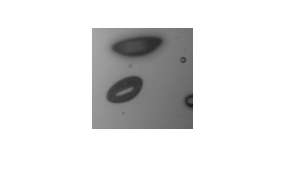

i = 22

ans =    151   151   100   100


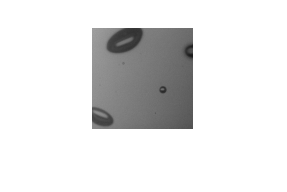

i = 23

ans =    151   201   100   100


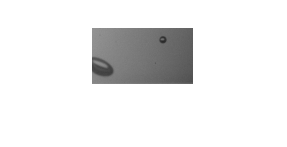

i = 24

ans =    151   251   100   100


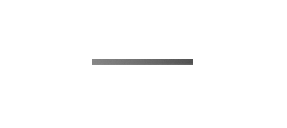

i = 25

ans =    201     1   100   100


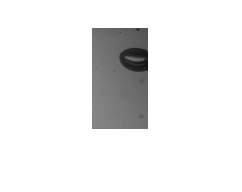

i = 26

ans =    201    51   100   100


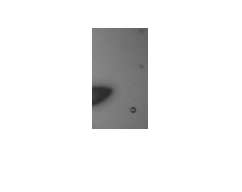

i = 27

ans =    201   101   100   100


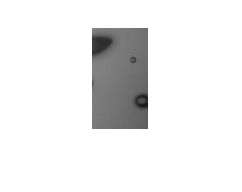

i = 28

ans =    201   151   100   100


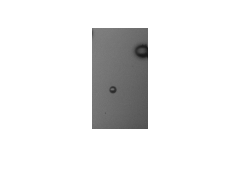

i = 29

ans =    201   201   100   100


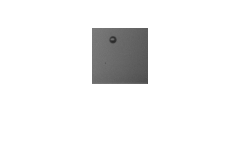

i = 30

ans =    201   251   100   100


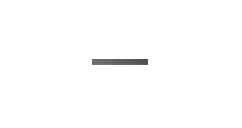

i = 31

ans =    251     1   100   100


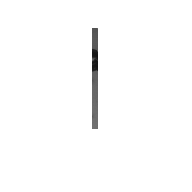

i = 32

ans =    251    51   100   100


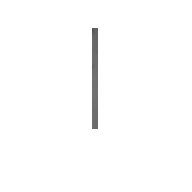

i = 33

ans =    251   101   100   100


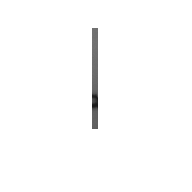

i = 34

ans =    251   151   100   100


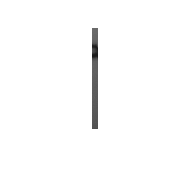

i = 35

ans =    251   201   100   100


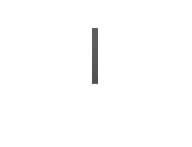

i = 36

ans =    251   251   100   100


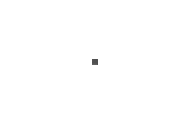


for x = 0:1:floor(size(I, 1)/sampling)
    for y = 0:1:floor(size(I, 2)/sampling)
        
        Xmin = x * sampling;
        Ymin = y * sampling;
        
        counter = counter + 1;
        tiles(counter, :) = [Xmin + 1, Ymin + 1, tilesize, tilesize];
    end
end
for i = 1:size(tiles, 1)
    i
    tiles(i, :)
    imcrop(I, tiles(i, :))
end